Лабораторная работа №3

Пространственная кинематика

Топольницкий А.

Вариант №53

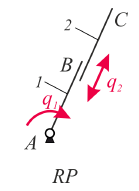

Рисунок 1.

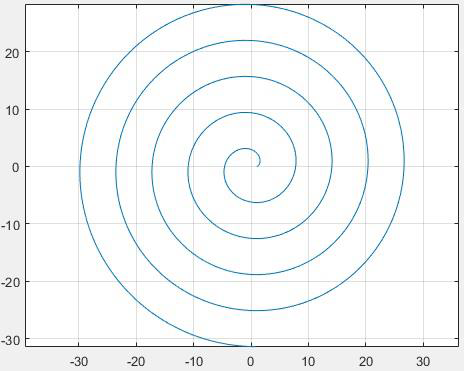

Исходные данные:

- Задана конфигурация робота, изображённая на Рисунке 1. Первое звено вращательное, второе призматическое, то есть схема RP

- Необходимо реализовать траекторию, изображённую на рисунке 2.

- Параметры звеньев следующие: $L1 = 0.56  \; m, \; M1 = 0.72 \; kg, \; L2 =0.59  \; m , \; M2 = 0.57  \; kg$

The task is to analytically solve direct kinematic task and compare the results with the data from transform sensor

- postition of an end effector

- positions of center of masses for both links

- twists of both links

- linear and rotational velosities for both links (CoM) and the end-effector

Перевод задания:

Необходимо аналитически решить прямую задачу кинематики и сравнить следующие результаты с данными из transform sensor:

- положение энд-эффектора

- положения центра масс двух звеньев

- Твисты двух звеньев

- Линейные и вращательные скорости для двух центров масс звеньев и энд-эффектора

Можно использовать любой метод управления (по положению с помощью ПИД-регулятора, по положению на основании динамической модели, по импедансу).

Будем использовать управление с помощью ПИД-регулятора

clc
clear all

L1 = 0.56; %Length 1 link m
L2 = 0.59; %Length 2 link m
AB = [L1 0.1 0.1]; %scales 1st link
BC = [L2 0.05 0.05]; %scales 2d link
m1 = 0.72; %Mass 1 kg
m2 = 0.57; %Mass 2 kg

Base = [0.2*L1 0.2*L1 0.2*L1]; %Base parametrs

%Controller coefficients
kp = 700;
ki = 350;
kd = 300;

kp2 = 700;
ki2 = 300;
kd2 = 300;

format short;
addpath(genpath('mr')); % we use function library by Kevin Lynch /
% мы используем библиотеку функций Кевина Линча


Variables / Переменные

$q_1, \; q_2 $ are the angles of rotations, $dq_1, \; dq_2$ are the angular velocities

$q_1, \; q_2$ являются углами поворота, $dq_1, \; dq_2$ являются угловыми скоростями

$l_1,\; l_2$ are lengths, $m_1, \;  m_2$ are masses, $j_{x_1}, j_{y_1}, j_{z_1}, j_{x_2}, j_{y_2}, j_{z_2}$ are inertias, and $g$ is gravity constant

$l_1,\; l_2$ длины, $m_1, \;  m_2$ массы, $j_{x_1}, j_{y_1}, j_{z_1}, j_{x_2}, j_{y_2}, j_{z_2}$ инерции, and $g$ гравитационная постоянная

syms q1 q2 dq1 dq2 fx fy fz
syms l1 l2 m1 m2 jx1 jy1 jz1 jx2 jy2 jz2 g 

Generalized coordinates are the angles of rotations, dq stands for the angular velocities / Обобщенные координаты - это углы поворота, dq обозначает угловые скорости

q = [q1, q2]; 
dq = [dq1, dq2];

Vectors of unit angular velocities / Векторы единичных угловых скоростей

w1=[0;-1;0]

w1 =      0
    -1
     0


w2=[0;0;0]

w2 =      0
     0
     0


Positon of joints / Расположение сочленений (радиусы векторы до солченений от frame)

r1=[0;0;0]

r1 =      0
     0
     0


r2=[l1;0;0]

$$r2 = \left(\begin{array}{c} l_{1}\\ 0\\ 0 \end{array}\right)$$

Vectors of translation motion / Векторы поступательного движения

v1_unit=-VecToso3(w1)*r1; 
% VecToso3 is a function from mr for skew-symmetric representation
% VecToso3 является функцией из mr для кососимметричного представления
v2_unit=-VecToso3(w2)*r2 + [1;0;0];

Twist

S1=[w1;v1_unit]

S1 =      0
    -1
     0
     0
     0
     0


S2=[w2;v2_unit]

$$S2 = \left(\begin{array}{c} 0\\ 0\\ 0\\ 1\\ 0\\ 0 \end{array}\right)$$

Home position of CoM and ee / Изначальные положения для центра масс и энд-эффектора

Here by Hc10 I have denoted $H_{c_1}^{0}$. Тут под Hc10 понимается $H_{c_1}^{0}$

Hc10_home=[eye(3,3), [l1/2;0;0];  0,0,0,1]

$$Hc10\_home = \left(\begin{array}{cccc} 1 & 0 & 0 & \frac{l_{1}}{2}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Hc20_home=[eye(3,3), [l1+l2/2;0;0];  0,0,0,1]

$$Hc20\_home = \left(\begin{array}{cccc} 1 & 0 & 0 & l_{1}+\frac{l_{2}}{2}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Hee0_home=[eye(3,3), [l1+l2;0;0];  0,0,0,1]

$$Hee0\_home = \left(\begin{array}{cccc} 1 & 0 & 0 & l_{1}+l_{2}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### Rotation matrixes / Матрицы поворота


$$R=e^{\tilde{w}}=I+\tilde{w}\sin{\theta}+\tilde{w}^2(1-\cos{\theta})$$


In code by Rij I have denoted $R_i^j$ / В коде под Rij я обозначил$R_i^j$

R10=eye(3,3)+VecToso3(w1)*sin(q1)+VecToso3(w1)^2*(1-cos(q1)) % matrix exponential rodrigues formula

$$R10 = \left(\begin{array}{ccc} \cos\left(q_{1}\right) & 0 & -\sin\left(q_{1}\right)\\ 0 & 1 & 0\\ \sin\left(q_{1}\right) & 0 & \cos\left(q_{1}\right) \end{array}\right)$$

R21=eye(3,3)+VecToso3(w2)*sin(q2)+VecToso3(w2)^2*(1-cos(q2))

$$R21 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

#### Homogeneous transformation matrixes / Однородная матрица преобразования 

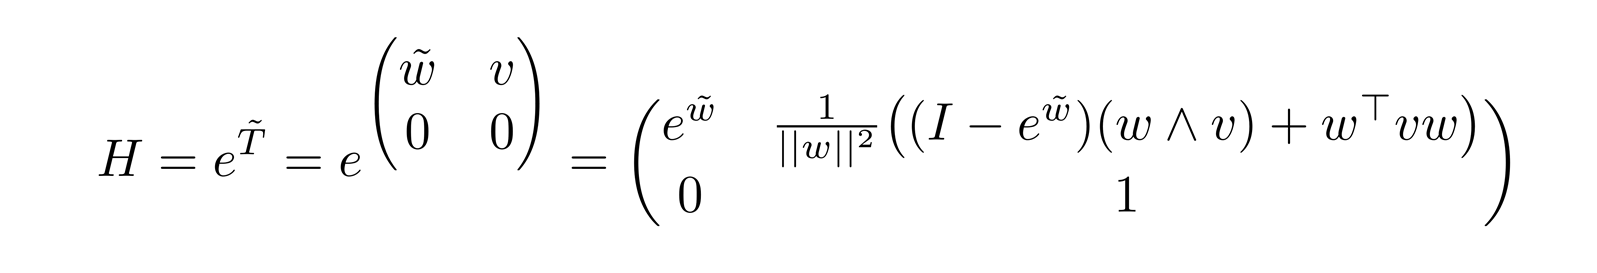

abs_ter_1=(eye(3,3)*q1+(1-cos(q1))*VecToso3(w1)+(q1-sin(q1))*VecToso3(w1)^2)*v1_unit;
abs_ter_2=(eye(3,3)*q2+(1-cos(q2))*VecToso3(w2)+(q2-sin(q2))*VecToso3(w2)^2)*v2_unit;

Here by T100 I have denoted $T_1^{0,0}$

e_T100q1=[R10, abs_ter_1; 0,0,0,1];
e_T201q2=[R21, abs_ter_2; 0,0,0,1];

#### Direct kinematics / Прямая кинематика


$$H_n^0 (q_1, q_2, \dots q_n)=
e^{\tilde{\hat{T}}_1^{0,0}q_1} e^{\tilde{\hat{T}}_2^{0,1}q_2} \dots
e^{\tilde{\hat{T}}_n^{0,(n-1)}q_n} H_n^{0}(0),
$$


Hc10=simplify(e_T100q1*Hc10_home)

$$Hc10 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & -\sin\left(q_{1}\right) & \frac{l_{1}\,\cos\left(q_{1}\right)}{2}\\ 0 & 1 & 0 & 0\\ \sin\left(q_{1}\right) & 0 & \cos\left(q_{1}\right) & \frac{l_{1}\,\sin\left(q_{1}\right)}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Hc20=simplify(e_T100q1*e_T201q2*Hc20_home)

$$Hc20 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & -\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\left(l_{1}+\frac{l_{2}}{2}+q_{2}\right)\\ 0 & 1 & 0 & 0\\ \sin\left(q_{1}\right) & 0 & \cos\left(q_{1}\right) & \sin\left(q_{1}\right)\,\left(l_{1}+\frac{l_{2}}{2}+q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Hee0=simplify(e_T100q1*e_T201q2*Hee0_home)

$$Hee0 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & -\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\left(l_{1}+l_{2}+q_{2}\right)\\ 0 & 1 & 0 & 0\\ \sin\left(q_{1}\right) & 0 & \cos\left(q_{1}\right) & \sin\left(q_{1}\right)\,\left(l_{1}+l_{2}+q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

P = Hee0*[0;0;0;1]

$$P = \left(\begin{array}{c} \cos\left(q_{1}\right)\,\left(l_{1}+l_{2}+q_{2}\right)\\ 0\\ \sin\left(q_{1}\right)\,\left(l_{1}+l_{2}+q_{2}\right)\\ 1 \end{array}\right)$$

P1 = Hc10 * [0;0;0;1]

$$P1 = \left(\begin{array}{c} \frac{l_{1}\,\cos\left(q_{1}\right)}{2}\\ 0\\ \frac{l_{1}\,\sin\left(q_{1}\right)}{2}\\ 1 \end{array}\right)$$

P2 = Hc20 * [0;0;0;1]

$$P2 = \left(\begin{array}{c} \cos\left(q_{1}\right)\,\left(l_{1}+\frac{l_{2}}{2}+q_{2}\right)\\ 0\\ \sin\left(q_{1}\right)\,\left(l_{1}+\frac{l_{2}}{2}+q_{2}\right)\\ 1 \end{array}\right)$$

Hc01 = TransInv(Hc10);
Hc02 = TransInv(Hc20);
H0ee = TransInv(Hee0)

$$H0ee = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right) & \left(-l_{1}-l_{2}-q_{2}\right)\,{\cos\left(q_{1}\right)}^{2}+\left(-l_{1}-l_{2}-q_{2}\right)\,{\sin\left(q_{1}\right)}^{2}\\ 0 & 1 & 0 & 0\\ -\sin\left(q_{1}\right) & 0 & \cos\left(q_{1}\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

TransInv is a function from mr to take an inverse of H / TransInv - это функция от mr чтобы брать обратную от  H

#### Geometriacal Jacobians / Геометрические матрицы якоби

J1 = S1;
J2 = simplify(Adjoint(e_T100q1*e_T201q2)*S2);
J_1 = [J1, zeros(6,1)];
J_2 = [J1, J2]

$$J\_2 = \left(\begin{array}{cc} 0 & 0\\ -1 & 0\\ 0 & 0\\ 0 & \cos\left(q_{1}\right)\\ 0 & 0\\ 0 & \sin\left(q_{1}\right) \end{array}\right)$$

Coordinates of CoM / z координаты центров масс

zc1 = [0, 0, 1, 0] * Hc10 * [0;0;0;1]

$$zc1 = \frac{l_{1}\,\sin\left(q_{1}\right)}{2}$$

zc2 = [0, 0, 1, 0] * Hc20 * [0;0;0;1]

$$zc2 = \sin\left(q_{1}\right)\,\left(l_{1}+\frac{l_{2}}{2}+q_{2}\right)$$

Inertia / инерция




L1 = 0.8; %Length 1 link m
L2 = 1; %Length 2 link m
AB = [L1 0.1 0.1]; %scales 1st link
BC = [L2 0.05 0.05]; %scales 2d link
m1 = 0.72; %Mass 1 kg
m2 = 0.57; %Mass 2 kg

Var2 
simout = sim('Var2');

x =
    1.8000

y =
     0

q1 =
     0

x =
    1.8000

y =
   1.8000e-08

q1 =
     0

x =
    1.8000

y =
     0

q1 =
     0

x =
    1.8000

y =
     0

q1 =
     0

x =
    1.8000

y =
     0

q1 =
     0

x =
    1.8000

y =
     0

q1 =
     0

x =
    1.8000

y =
     0

q1 =
     0

x =
    1.8000

y =
     0

q1 =
     0

x =
    1.8000

y =
     0

q1 =
     0

x =
    1.8000

y =
     0

q1 =
     0

x =
    1.8000

y =
     0

q1 =
     0

x =
    1.8000

y =
     0

q1 =
   1.6939e-13

x =
    1.8000

y =
  -3.1777e-10

q1 =
   3.8113e-13

x =
    1.8000

y =
  -2.2597e-09

q1 =
   2.7103e-12

x =
    1.8000

y =
  -2.7897e-09

q1 =
   3.3460e-12

x =
    1.8000

y =
  -3.5308e-09

q1 =
   4.2348e-12

x =
    1.8000

y =
  -3.5308e-09

q1 =
   4.2348e-12

x =
    1.8000

y =
  -3.5308e-09

q1 =
   4.2348e-12

x =
    1.8000

y =
  -1.0592e-08

q1 =
   1.6939e-11

x =
    1.8000

y =
  -2.2067e-08

q1 =
   2.6467e-11

x =
    1.8000

y =
  -8.8269e-08

q1 =
   1.0587e-10


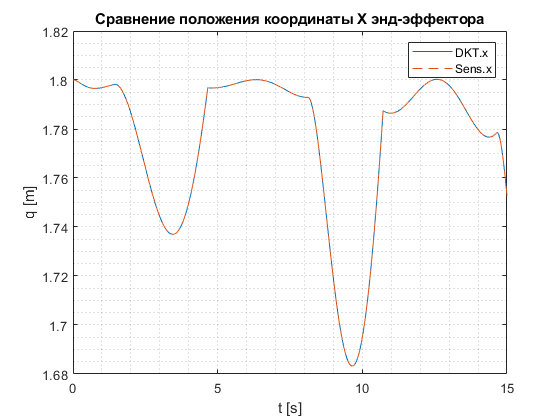


figure;
plot(simout.sim.DKT_call.time, simout.sim.DKT_call.Data(:,1))
hold on
plot(simout.sim.DKT_sens.x.time, simout.sim.DKT_sens.x.Data, "LineStyle",'--')
grid minor
legend('DKT.x','Sens.x')
xlabel('t [s]');
ylabel('q [m]');
title('Сравнение положения координаты Х энд-эффектора')

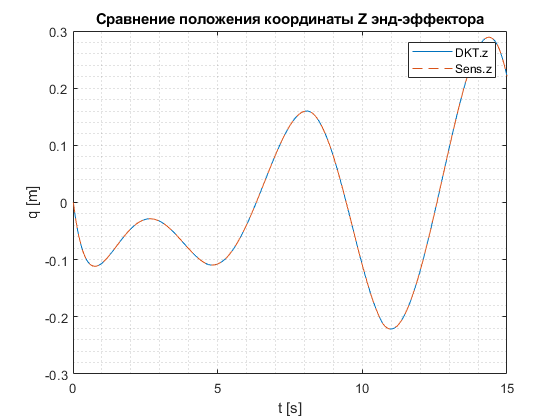

figure;
plot(simout.sim.DKT_call.time, simout.sim.DKT_call.Data(:,3))
hold on
plot(simout.sim.DKT_sens.z.time, simout.sim.DKT_sens.z.Data, "LineStyle",'--')
grid minor
legend('DKT.z','Sens.z')
xlabel('t [s]');
ylabel('q [m]');
title('Сравнение положения координаты Z энд-эффектора')

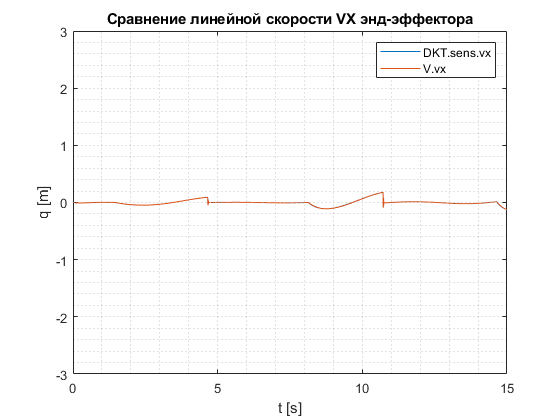

figure;
plot(simout.sim.DKT_sens.vx.time,simout.sim.DKT_sens.vx.Data)
hold on
plot(simout.sim.V.time,simout.sim.V.Data(:,1))
grid minor
xlabel('t [s]');
ylabel('q [m]');
title('Сравнение линейной скорости VX энд-эффектора')
legend('DKT.sens.vx','V.vx')
ylim([-3 3]);

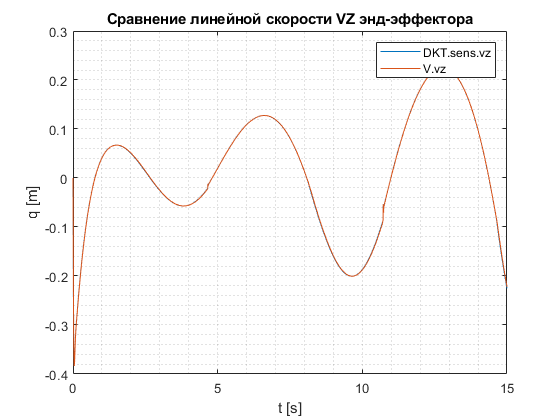

figure;
plot(simout.sim.DKT_sens.vz.time,simout.sim.DKT_sens.vz.Data)
hold on
plot(simout.sim.V.time,simout.sim.V.Data(:,3))
grid minor
xlabel('t [s]');
ylabel('q [m]');
title('Сравнение линейной скорости VZ энд-эффектора')
legend('DKT.sens.vz','V.vz')

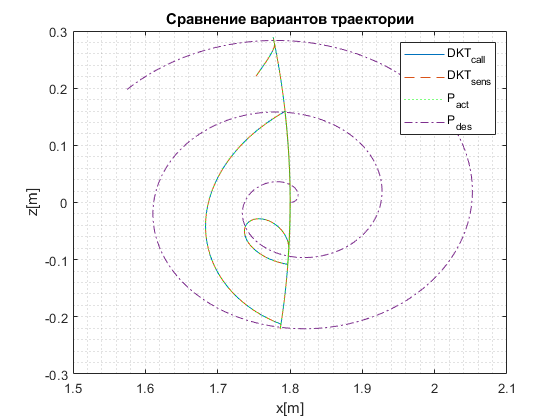


figure;
plot(simout.sim.DKT_call.Data(:,1), simout.sim.DKT_call.Data(:,3))
hold on
plot(simout.sim.DKT_sens.x.Data, simout.sim.DKT_sens.z.Data, 'LineStyle','--')
grid minor
plot(simout.lab2.x_act.Data, simout.lab2.y_act.Data,'LineStyle',':','Color','g')
plot(simout.lab2.x_des.Data, simout.lab2.y_des.Data,'LineStyle','-.')
legend('DKT_{call}','DKT_{sens}','P_{act}','P_{des}')
title('Сравнение вариантов траектории')
xlabel('x[m]')
ylabel('z[m]')

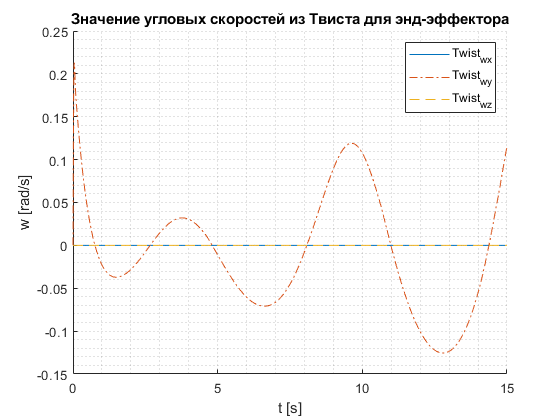

figure;
hold on
plot(simout.sim.Twist.time,simout.sim.Twist.Data(:,1))
plot(simout.sim.Twist.time,simout.sim.Twist.Data(:,2), 'LineStyle','-.')
plot(simout.sim.Twist.time,simout.sim.Twist.Data(:,3),'LineStyle','--')
title('Значение угловых скоростей из Твиста для энд-эффектора')
legend('Twist_{wx}','Twist_{wy}','Twist_{wz}')
grid minor
xlabel('t [s]');
ylabel('w [rad/s]')

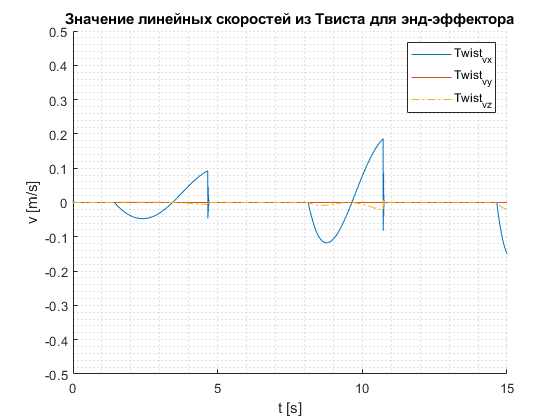

figure;
hold on
plot(simout.sim.Twist.time,simout.sim.Twist.Data(:,4), 'LineStyle','-')
plot(simout.sim.Twist.time,simout.sim.Twist.Data(:,5), 'LineStyle','-')
plot(simout.sim.Twist.time,simout.sim.Twist.Data(:,6), 'LineStyle','-.')
title('Значение линейных скоростей из Твиста для энд-эффектора')
legend('Twist_{vx}','Twist_{vy}','Twist_{vz}')
grid minor
xlabel('t [s]');
ylabel('v [m/s]')
ylim([-0.5,0.5])

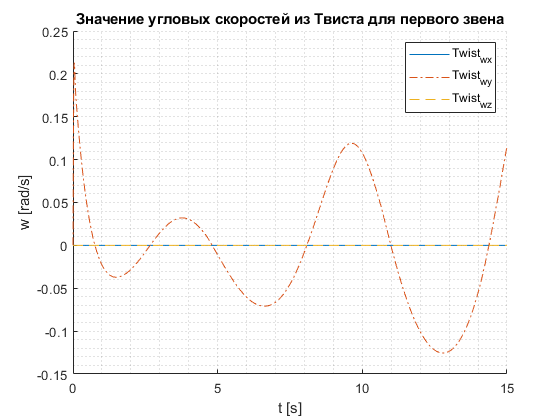

figure;
hold on
plot(simout.sim.Twist1.time,simout.sim.Twist1.Data(:,1))
plot(simout.sim.Twist1.time,simout.sim.Twist1.Data(:,2), 'LineStyle','-.')
plot(simout.sim.Twist1.time,simout.sim.Twist1.Data(:,3),'LineStyle','--')
title('Значение угловых скоростей из Твиста для первого звена')
legend('Twist_{wx}','Twist_{wy}','Twist_{wz}')
grid minor
xlabel('t [s]');
ylabel('w [rad/s]')

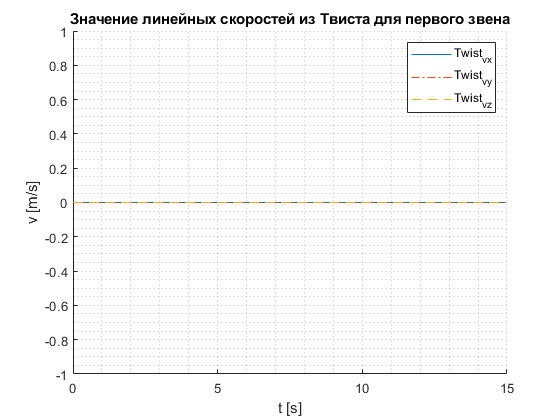


figure;
hold on
plot(simout.sim.Twist1.time,simout.sim.Twist1.Data(:,4))
plot(simout.sim.Twist1.time,simout.sim.Twist1.Data(:,5), 'LineStyle','-.')
plot(simout.sim.Twist1.time,simout.sim.Twist1.Data(:,6),'LineStyle','--')
title('Значение линейных скоростей из Твиста для первого звена')
legend('Twist_{vx}','Twist_{vy}','Twist_{vz}')
grid minor
xlabel('t [s]');
ylabel('v [m/s]')

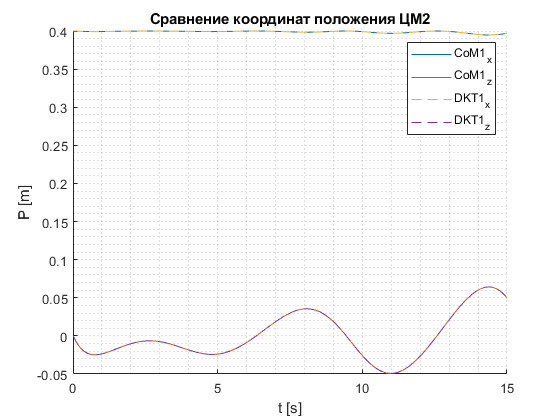


figure;
hold on
grid minor
plot(simout.sim.CoM1.x.time,simout.sim.CoM1.x.Data)
plot(simout.sim.CoM1.z.time,simout.sim.CoM1.z.Data)
plot(simout.sim.DKT_1.time,simout.sim.DKT_1.Data(:,1), 'LineStyle','--')
plot(simout.sim.DKT_1.time,simout.sim.DKT_1.Data(:,3),'LineStyle','--')
xlabel('t [s]')
ylabel('P [m]')
legend('CoM1_x','CoM1_z','DKT1_x','DKT1_z')
title('Сравнение координат положения ЦМ2')

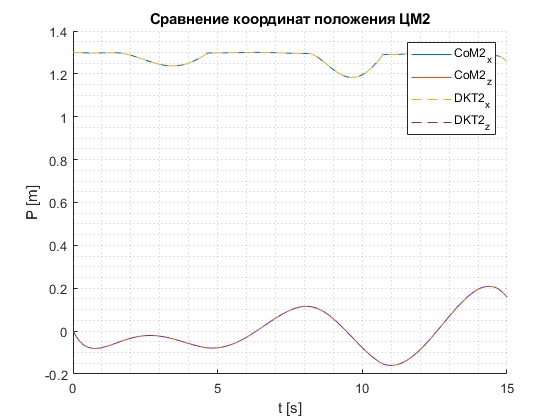


figure;
hold on
grid minor
plot(simout.sim.CoM2.x.time,simout.sim.CoM2.x.Data)
plot(simout.sim.CoM2.z.time,simout.sim.CoM2.z.Data)
plot(simout.sim.DKT_2.time,simout.sim.DKT_2.Data(:,1), 'LineStyle','--')
plot(simout.sim.DKT_2.time,simout.sim.DKT_2.Data(:,3),'LineStyle','--')
xlabel('t [s]')
ylabel('P [m]')
legend('CoM2_x','CoM2_z','DKT2_x','DKT2_z')
title('Сравнение координат положения ЦМ2')

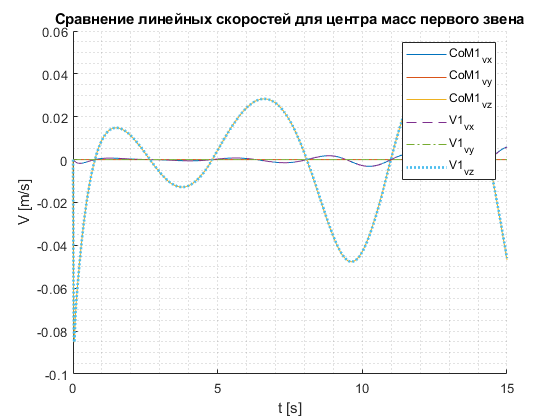

figure;
hold on
grid minor
plot(simout.sim.CoM1.vx.time,simout.sim.CoM1.vx.Data)
plot(simout.sim.CoM1.vy.time,simout.sim.CoM1.vy.Data)
plot(simout.sim.CoM1.vz.time,simout.sim.CoM1.vz.Data)
plot(simout.sim.V1.time,simout.sim.V1.Data(:,1), 'LineStyle','--')
plot(simout.sim.V1.time,simout.sim.V1.Data(:,2), 'LineStyle','-.')
plot(simout.sim.V1.time,simout.sim.V1.Data(:,3), 'LineStyle',':','LineWidth',2)
xlabel('t [s]')
ylabel('V [m/s]')
legend('CoM1_{vx}','CoM1_{vy}','CoM1_{vz}','V1_{vx}','V1_{vy}','V1_{vz}')
title('Сравнение линейных скоростей для центра масс первого звена')

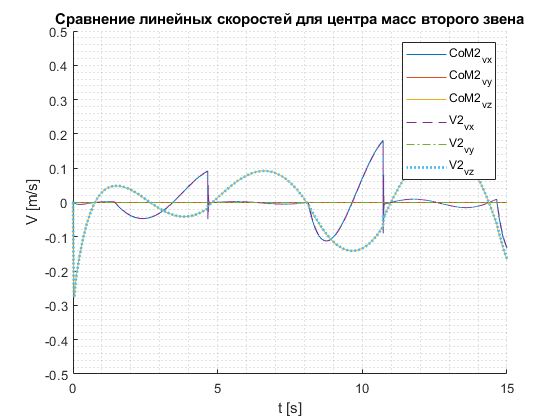


figure;
hold on
grid minor
plot(simout.sim.CoM2.vx.time,simout.sim.CoM2.vx.Data)
plot(simout.sim.CoM2.vy.time,simout.sim.CoM2.vy.Data)
plot(simout.sim.CoM2.vz.time,simout.sim.CoM2.vz.Data)
plot(simout.sim.V2.time,simout.sim.V2.Data(:,1), 'LineStyle','--')
plot(simout.sim.V2.time,simout.sim.V2.Data(:,2), 'LineStyle','-.')
plot(simout.sim.V2.time,simout.sim.V2.Data(:,3), 'LineStyle',':','LineWidth',2)
xlabel('t [s]')
ylabel('V [m/s]')
legend('CoM2_{vx}','CoM2_{vy}','CoM2_{vz}','V2_{vx}','V2_{vy}','V2_{vz}')
title('Сравнение линейных скоростей для центра масс второго звена')
ylim([-0.5,0.5])

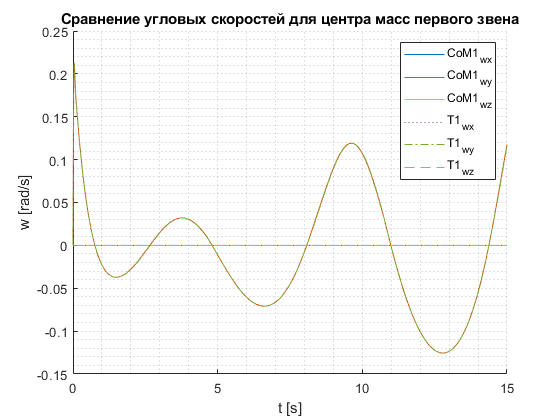

figure;
hold on
grid minor
plot(simout.sim.CoM1.wx.time,simout.sim.CoM1.wx.Data)
plot(simout.sim.CoM1.wy.time,simout.sim.CoM1.wy.Data)
plot(simout.sim.CoM1.wz.time,simout.sim.CoM1.wz.Data)
plot(simout.sim.Twist1.time,simout.sim.Twist1.Data(:,1), 'LineStyle',':')
plot(simout.sim.Twist1.time,simout.sim.Twist1.Data(:,2), 'LineStyle','-.')
plot(simout.sim.Twist1.time,simout.sim.Twist1.Data(:,3),'LineStyle','--')
xlabel('t [s]');
ylabel('w [rad/s]')
legend('CoM1_{wx}','CoM1_{wy}','CoM1_{wz}','T1_{wx}','T1_{wy}','T1_{wz}')
title('Сравнение угловых скоростей для центра масс первого звена')

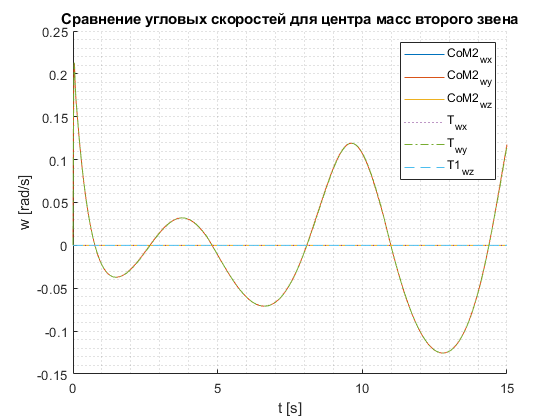


figure;
hold on
grid minor
plot(simout.sim.CoM2.wx.time,simout.sim.CoM2.wx.Data)
plot(simout.sim.CoM2.wy.time,simout.sim.CoM2.wy.Data)
plot(simout.sim.CoM2.wz.time,simout.sim.CoM2.wz.Data)
plot(simout.sim.Twist.time,simout.sim.Twist.Data(:,1), 'LineStyle',':')
plot(simout.sim.Twist.time,simout.sim.Twist.Data(:,2), 'LineStyle','-.')
plot(simout.sim.Twist.time,simout.sim.Twist.Data(:,3),'LineStyle','--')
xlabel('t [s]');
ylabel('w [rad/s]')
legend('CoM2_{wx}','CoM2_{wy}','CoM2_{wz}','T_{wx}','T_{wy}','T1_{wz}')
title('Сравнение угловых скоростей для центра масс второго звена')

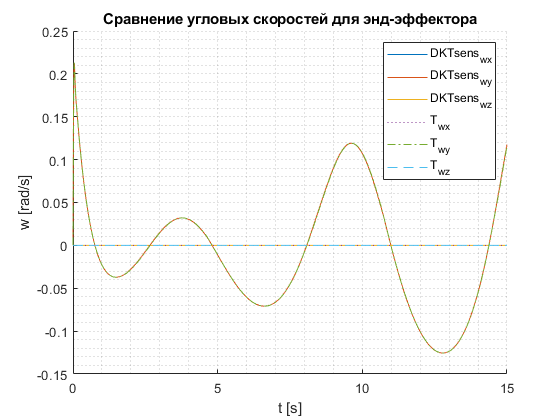

figure;
hold on
grid minor
plot(simout.sim.DKT_sens.wx.time,simout.sim.DKT_sens.wx.Data)
plot(simout.sim.DKT_sens.wy.time,simout.sim.DKT_sens.wy.Data)
plot(simout.sim.DKT_sens.wz.time,simout.sim.DKT_sens.wz.Data)
plot(simout.sim.Twist.time,simout.sim.Twist.Data(:,1), 'LineStyle',':')
plot(simout.sim.Twist.time,simout.sim.Twist.Data(:,2), 'LineStyle','-.')
plot(simout.sim.Twist.time,simout.sim.Twist.Data(:,3),'LineStyle','--')
xlabel('t [s]');
ylabel('w [rad/s]')
legend('DKTsens_{wx}','DKTsens_{wy}','DKTsens_{wz}','T_{wx}','T_{wy}','T_{wz}')
title('Сравнение угловых скоростей для энд-эффектора')

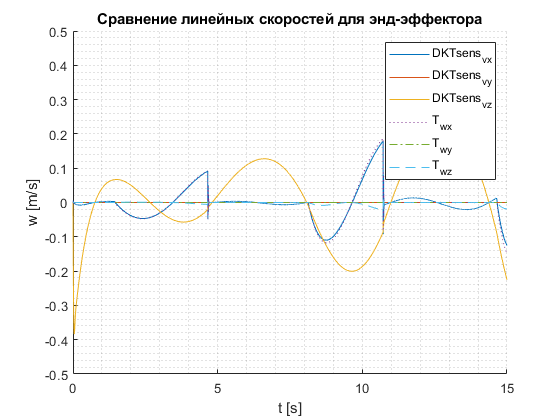

figure;
hold on
grid minor
plot(simout.sim.DKT_sens.vx.time,simout.sim.DKT_sens.vx.Data)
plot(simout.sim.DKT_sens.vy.time,simout.sim.DKT_sens.vy.Data)
plot(simout.sim.DKT_sens.vz.time,simout.sim.DKT_sens.vz.Data)
plot(simout.sim.Twist.time,simout.sim.Twist.Data(:,4), 'LineStyle',':')
plot(simout.sim.Twist.time,simout.sim.Twist.Data(:,5), 'LineStyle','-.')
plot(simout.sim.Twist.time,simout.sim.Twist.Data(:,6),'LineStyle','--')
xlabel('t [s]');
ylabel('w [m/s]')
legend('DKTsens_{vx}','DKTsens_{vy}','DKTsens_{vz}','T_{wx}','T_{wy}','T_{wz}')
title('Сравнение линейных скоростей для энд-эффектора')
ylim([-0.5,0.5])